%-----APLICANDO LAS PROPIEDADES 
clear all;
close all;
clc;
%-----Gráfica señal original-----
Fs=100;
t=-1:1/Fs:2;
L=3000;         %Longitud de la señal 
A=-2

A = -2

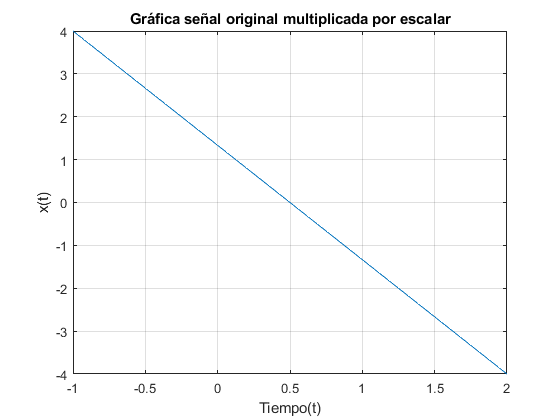

s=A*((4/3)*t-2/3);
Y=fft(s,L);     %Aplicando transformada rápida

plot(t,s);
title('Gráfica señal original multiplicada por escalar')
xlabel('Tiempo(t)');
ylabel('x(t)');
grid on

figure

P=abs(Y/Fs);
f=linspace(0,Fs,numel(P));

plot(f,P)
axis ([0 5 0 3])
title('Gráfica transformada rápida y teórica')
xlabel('Frecuencia(rad/s)')
ylabel('|X(f)|')
grid on


%-----Multiplicación por escalar
syms t f;       %Variables simbólicas
e=-2

e = -2

xe= e*((4/3)*t-2/3);  %Señal por escalar
ye=int(xe*exp(-1i*2*pi*f*t),t,-1,2) %Transformada de Fourier teórica

$$ye = -\frac{2\,{\mathrm{e}}^{-4\,\pi \,f\,\mathrm{i}}\,\left(1-{\mathrm{e}}^{6\,\pi \,f\,\mathrm{i}}+3\,\pi \,f\,\mathrm{i}+3\,\pi \,f\,{\mathrm{e}}^{6\,\pi \,f\,\mathrm{i}}\,\mathrm{i}\right)}{3\,f^{2}\,\pi^{2}}$$

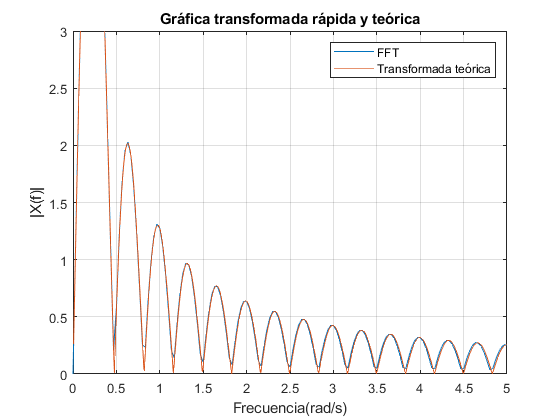

hold on         %sobreposición
fplot(f,abs(ye),[0 5])
legend('FFT','Transformada teórica')
grid on

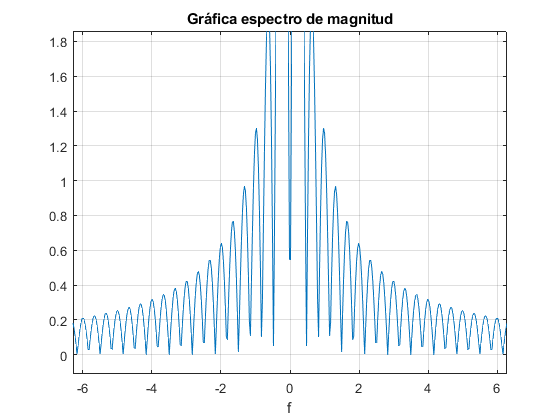

figure

%-----Gráfica espectro de magnitud
ezplot(abs(ye));
title('Gráfica espectro de magnitud')
grid on